%Sanskruti's Code
A=[-10 -2 -5;11 -30 -21;5 10 2];
B=[1;2;7];
C=[2 1 5];
Q=C'*C

Q =      4     2    10
     2     1     5
    10     5    25


L0=lyap(A',Q)

L0 =     1.1831    0.3756    1.1398
    0.3756    0.1487    0.4712
    1.1398    0.4712    1.5475


H=trace(B'*L0*B)

H = 108.2603

sys=ss(A,B,C,0);
norm(sys,2)

ans = 10.4048

%H2 norm Harsh
A=[-10 2 5;11 -30 -21;5 10 3]; B=[1;2;1];
C=[1 -1 0];
vecB=reshape(B*B',9,1);
Lc=-(inv(kron(eye(3),A)+kron(A,eye(3))))*vecB;
Lc=reshape(Lc,3,3)

Lc =     0.8789   -1.0456    2.0761
   -1.0456    1.4839   -2.5724
    2.0761   -2.5724    4.9477


trace(C*Lc*C')

ans = 4.4540

sys=ss(A,B,C,0);
norm(sys,2)

ans = 2.1105

Lc=lyap(A,B*B')

Lc =     0.8789   -1.0456    2.0761
   -1.0456    1.4839   -2.5724
    2.0761   -2.5724    4.9477


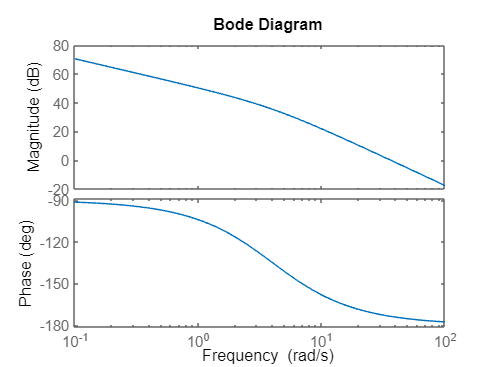

Kp=1334;
den=[1 4 0];
num=Kp;
sys=tf(num,den);
bode(sys);

%Harsh pole placement
A1=[1 -2 5;11 3 -21;5 10 -8]; B1=[1;2;1];
M1=[B1 A1*B1 A1*A1*B1];
W1=inv(M1)

W1 =     0.6470    0.1920   -0.0310
   -0.0015   -0.0257    0.0529
    0.0037   -0.0015   -0.0008


P1=[W1(3,:);W1(3,:)*A1;W1(3,:)*A1*A1]; %T inverse
Ac1=P1*A1*inv(P1)

Ac1 =    -0.0000    1.0000   -0.0000
    0.0000    0.0000    1.0000
  695.0000 -178.0000   -4.0000


Bc1=P1*B1

Bc1 =     0.0000
    0.0000
    1.0000


K1=[-15695 -1672 -71];
K=K1*P1

K =   -34.5404   18.3975  -73.2547


place(A1,B1,[-20,-25,-30])

ans =    34.5404  -18.3975   73.2547


A=[-10 2 5;11 -30 -21;5 10 3]; B=[1;2;1];
K=place(A,B,[-20,-25,-30]);
rank(A+B*K)

ans = 3

A=[-10 2 5;11 -30 -21;5 10 3]; 
C=[1 -1 0];
L=place(A',C',[-20,-25,-30]);
rank(A'-L*C')

ans = 3

%pole placement
A=[1 -2 5;11 3 -21;5 10 -8];
B=[1;2;-1];
clp=[-20;-25;-30];
M=[B A*B A*A*B];
W=inv(M);
P=[W(3,:);W(3,:)*A;W(3,:)*A*A]

P =     0.0036   -0.0009    0.0018
    0.0034    0.0088    0.0210
    0.2052    0.2295   -0.3358


Acl=P*A*inv(P)

Acl =     0.0000    1.0000         0
    0.0000   -0.0000    1.0000
  695.0000 -178.0000   -4.0000


Bcl=P*B;

K1=[-695-15000 178-1850 4-75]

K1 =       -15695       -1672         -71


K=K1*P

K =   -76.1281  -17.5750  -40.2781


place(A,B,clp)

ans =    76.1281   17.5750   40.2781


%lyapunov functions
A=[1 -2 5;11 3 -21;5 10 -8];
B=[1;2;-1];
clp=[-20;-25;-30];
K=place(A,B,clp)

K =    76.1281   17.5750   40.2781


Acl=(A-B*K);
Q=-eye(3);
vecQ=reshape(Q,9,1);
VecP=inv(kron(eye(3),Acl)+kron(Acl,eye(3)))*vecQ;
P=reshape(VecP,3,3)

P =     0.0796   -0.1523   -0.0710
   -0.1523    0.5525    0.0418
   -0.0710    0.0418    0.1271


lyap(Acl,Q)

ans =    -0.0796    0.1523    0.0710
    0.1523   -0.5525   -0.0418
    0.0710   -0.0418   -0.1271


%Hamiltionian Control Harsh
A=[1 -2 5;11 3 -21;5 10 -8];
B=[1;2;-1];
C=[1 2 -1];
Q=eye(3);
R=1;
H=[A -B*inv(R)*B';-Q -A'];
[V,D]=eig(H)

V =    0.1490 - 0.1201i   0.1490 + 0.1201i   0.0233 + 0.0284i   0.0233 - 0.0284i  -0.8676 + 0.0000i  -0.1774 + 0.0000i
  -0.8122 + 0.0000i  -0.8122 + 0.0000i  -0.0659 + 0.4498i  -0.0659 - 0.4498i  -0.1108 + 0.0000i   0.2075 + 0.0000i
  -0.1895 + 0.4959i  -0.1895 - 0.4959i   0.1837 + 0.1046i   0.1837 - 0.1046i  -0.4623 + 0.0000i   0.0595 + 0.0000i
  -0.0078 - 0.0504i  -0.0078 + 0.0504i   0.3139 + 0.0425i   0.3139 - 0.0425i   0.1413 + 0.0000i  -0.9308 + 0.0000i
  -0.0846 - 0.0409i  -0.0846 + 0.0409i   0.1968 - 0.4193i   0.1968 + 0.4193i   0.0038 + 0.0000i  -0.1021 + 0.0000i
   0.0112 + 0.1016i   0.0112 - 0.1016i  -0.6576 + 0.0000i  -0.6576 + 0.0000i   0.0369 + 0.0000i  -0.2124 + 0.0000i


D =   -4.3814 +13.8728i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -4.3814 -13.8728i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   4.3814 +13.8728i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.3814 -13.8728i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.5380 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.5380 + 0.0000i


XY=[V(:,1) V(:,2) V(:,6)]

XY =    0.1490 - 0.1201i   0.1490 + 0.1201i  -0.1774 + 0.0000i
  -0.8122 + 0.0000i  -0.8122 + 0.0000i   0.2075 + 0.0000i
  -0.1895 + 0.4959i  -0.1895 - 0.4959i   0.0595 + 0.0000i
  -0.0078 - 0.0504i  -0.0078 + 0.0504i  -0.9308 + 0.0000i
  -0.0846 - 0.0409i  -0.0846 + 0.0409i  -0.1021 + 0.0000i
   0.0112 + 0.1016i   0.0112 - 0.1016i  -0.2124 + 0.0000i


X=XY(1:3,:);
Y=XY(4:6,:);
P=Y*inv(X)

P =    6.8170 + 0.0000i   0.8984 + 0.0000i   1.5500 + 0.0000i
   0.8984 + 0.0000i   0.2375 + 0.0000i   0.1351 + 0.0000i
   1.5500 - 0.0000i   0.1351 + 0.0000i   0.5805 - 0.0000i


sys=ss(A,B,C,0);
[K,P,CLD]=lqr(sys,Q,R);
P

P =     6.8170    0.8984    1.5500
    0.8984    0.2375    0.1351
    1.5500    0.1351    0.5805


A1=[1 -2 5;11 3 -21;5 10 -8]; B1=[1 0 0];
M1=[B1' A1'*B1' A1'*A1'*B1'];
W1=inv(M1)

W1 =     1.0000   -0.0580   -0.2232
         0   -0.0313    0.1875
         0    0.0223    0.0089


P1=[W1(3,:);W1(3,:)*A1';W1(3,:)*A1'*A1']; %T inverse
Ac1=P1*A1'*inv(P1)

Ac1 =          0    1.0000   -0.0000
         0    0.0000    1.0000
  695.0000 -178.0000   -4.0000


Bc1=P1*B1'

Bc1 =          0
    0.0000
    1.0000


K1=[-15695 -1672 -71];
K=K1*P1

K =   -71.0000  103.1875 -222.1250


place(A1',B1',[-20,-25,-30])

ans =    71.0000 -103.1875  222.1250
